%20
% [H, g, A1, A2, b1, b2] = generate_random_qp(20,5,3);
% y = IRWA_QP_scaling(A1, A2, -b1, -b2, g, H);
% result_20_scaling = y' * H * y / 2 + g' * y;
% 
% y = QP(A1, A2, -b1, -b2, g, H);
% result_20_QP = y' * H * y / 2 + g' * y;
% 
% y = QP_origin(A1, A2, -b1, -b2, g, H);
% result_20_QP_origin = y' * H * y / 2 + g' * y;
% 
% y = IRWA_QP_scaling_no_max(A1, A2, -b1, -b2, g, H);
% result_20_QP_scaling_no_max = y' * H * y / 2 + g' * y;
% 
% [A, l, u] = standard_constraints(A2,b2,A1,b1);
% m = osqp;
% m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);
% results = m.solve();
% x_20_osqp = results.x;
% result_20_osqp = x_20_osqp'*H*x_20_osqp/2+g'*x_20_osqp;

% Initialize results storage
dims = [10, 20, 50, 100, 150, 200, 250, 300, 350, 400, 450, 500];
% dims = [50];
results_scaling = zeros(size(dims));
results_QP = zeros(size(dims));
results_QP_origin = zeros(size(dims));
results_scaling_no_max = zeros(size(dims));
results_osqp = zeros(size(dims));

for i = 1:length(dims)
    n = dims(i);
    [H, g, A1, A2, b1, b2] = generate_random_qp(n, floor(n/4), floor(n/6));

    y = IRWA_QP_scaling(A1, A2, -b1, -b2, g, H);
    results_scaling(i) = y' * H * y / 2 + g' * y;

    y = QP(A1, A2, -b1, -b2, g, H);
    results_QP(i) = y' * H * y / 2 + g' * y;

    y = QP_origin(A1, A2, -b1, -b2, g, H);
    results_QP_origin(i) = y' * H * y / 2 + g' * y;

    y = IRWA_QP_scaling_no_max(A1, A2, -b1, -b2, g, H);
    results_scaling_no_max(i) = y' * H * y / 2 + g' * y;

    [A, l, u] = standard_constraints(A2,b2,A1,b1);
    m = osqp;
    m.setup(H, g, A, l, u, 'eps_abs', 1e-06, 'eps_rel', 1e-06);
    results = m.solve();
    x_osqp = results.x;
    results_osqp(i) = x_osqp' * H * x_osqp / 2 + g' * x_osqp;
end

-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 10, constraints m = 3
          nnz(P) + nnz(A) = 85
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -4.1753e-01   1.10e+00   6.05e+02   1.00e-01   1.41e-04s
  50   2.4894e+00   1.40e-09   8.15e-09   1.00e-01   3.09e-04s

status:               solved
number of iterations: 50
optimal objective:    2.4894
run time:             4.63e-04s
optimal rho estimate: 8.89e-02



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 20, constraints m = 8
          nnz(P) + nnz(A) = 370
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.3291e-01   1.59e+00   1.37e+03   1.00e-01   1.70e-04s
  50  -5.5060e-01   2.30e-09   1.61e-08   1.00e-01   3.70e-04s

status:               solved
number of iterations: 50
optimal objective:    -0.5506
run time:             6.00e-04s
optimal rho estimate: 5.55e-02



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 50, constraints m = 20
          nnz(P) + nnz(A) = 2275
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -8.1186e-01   3.11e+00   4.97e+03   1.00e-01   5.79e-04s
  50   2.6367e+00   3.59e-09   6.90e-08   1.00e-01   9.01e-04s

status:               solved
number of iterations: 50
optimal objective:    2.6367
run time:             1.06e-03s
optimal rho estimate: 3.41e-02



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 100, constraints m = 41
          nnz(P) + nnz(A) = 9150
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -8.6903e-01   2.59e+00   1.66e+04   1.00e-01   1.21e-03s
  50   9.0275e+00   4.80e-09   2.19e-07   1.00e-01   1.86e-03s

status:               solved
number of iterations: 50
optimal objective:    9.0275
run time:             2.00e-03s
optimal rho estimate: 3.25e-02



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 150, constraints m = 62
          nnz(P) + nnz(A) = 20625
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.2466e-01   2.18e+00   3.50e+04   1.00e-01   3.47e-03s
  75   1.4442e+01   1.46e-07   7.03e-06   1.00e-01   5.67e-03s

status:               solved
number of iterations: 75
optimal objective:    14.4423
run time:             5.91e-03s
optimal rho estimate: 2.60e-02



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 200, constraints m = 83
          nnz(P) + nnz(A) = 36700
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -5.8331e-01   2.26e+00   5.63e+04   1.00e-01   7.64e-03s
  75   2.3159e+01   1.24e-08   9.91e-07   1.00e-01   1.24e-02s

status:               solved
number of iterations: 75
optimal objective:    23.1588
run time:             1.27e-02s
optimal rho estimate: 2.71e-02



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 250, constraints m = 103
          nnz(P) + nnz(A) = 57125
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -7.7163e-01   2.24e+00   7.58e+04   1.00e-01   1.33e-02s
  75   1.8264e+01   5.34e-11   5.79e-11   1.59e-02   2.50e-02s

status:               solved
number of iterations: 75
optimal objective:    18.2639
run time:             2.53e-02s
optimal rho estimate: 3.72e-02



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 300, constraints m = 125
          nnz(P) + nnz(A) = 82650
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.7401e-01   2.33e+00   9.78e+04   1.00e-01   2.90e-02s
 125   1.6608e+01   4.75e-11   5.83e-11   1.21e-02   6.69e-02s

status:               solved
number of iterations: 125
optimal objective:    16.6082
run time:             6.74e-02s
optimal rho estimate: 2.44e-02



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 350, constraints m = 145
          nnz(P) + nnz(A) = 112175
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -5.9153e-01   2.98e+00   1.05e+05   1.00e-01   4.91e-02s
  75   2.3499e+01   2.63e-08   1.81e-08   8.26e-03   9.37e-02s

status:               solved
number of iterations: 75
optimal objective:    23.4993
run time:             9.42e-02s
optimal rho estimate: 2.16e-02



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 400, constraints m = 166
          nnz(P) + nnz(A) = 146600
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -5.9806e-01   2.73e+00   1.23e+05   1.00e-01   6.49e-02s
 100   4.3436e+01   5.23e-11   3.06e-10   1.28e-02   1.33e-01s

status:               solved
number of iterations: 100
optimal objective:    43.4358
run time:             1.33e-01s
optimal rho estimate: 1.53e-02



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 450, constraints m = 187
          nnz(P) + nnz(A) = 185625
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.6622e-01   3.88e+00   1.37e+05   1.00e-01   9.18e-02s
 175   3.1680e+01   6.21e-10   5.20e-10   7.28e-03   2.17e-01s

status:               solved
number of iterations: 175
optimal objective:    31.6801
run time:             2.25e-01s
optimal rho estimate: 1.61e-02



-----------------------------------------------------------------
           OSQP v0.6.2  -  Operator Splitting QP Solver
              (c) Bartolomeo Stellato,  Goran Banjac
        University of Oxford  -  Stanford University 2021
-----------------------------------------------------------------
problem:  variables n = 500, constraints m = 208
          nnz(P) + nnz(A) = 229250
settings: linear system solver = qdldl,
          eps_abs = 1.0e-06, eps_rel = 1.0e-06,
          eps_prim_inf = 1.0e-04, eps_dual_inf = 1.0e-04,
          rho = 1.00e-01 (adaptive),
          sigma = 1.00e-06, alpha = 1.60, max_iter = 4000
          check_termination: on (interval 25),
          scaling: on, scaled_termination: off
          warm start: on, polish: off, time_limit: off



iter  objective    pri res    dua res    rho        time
   1  -6.4334e-01   2.69e+00   1.55e+05   1.00e-01   1.46e-01s
 150   5.5540e+01   1.34e-08   1.02e-05   1.00e-01   2.29e-01s

status:               solved
number of iterations: 150
optimal objective:    55.5403
run time:             2.29e-01s
optimal rho estimate: 1.07e-02



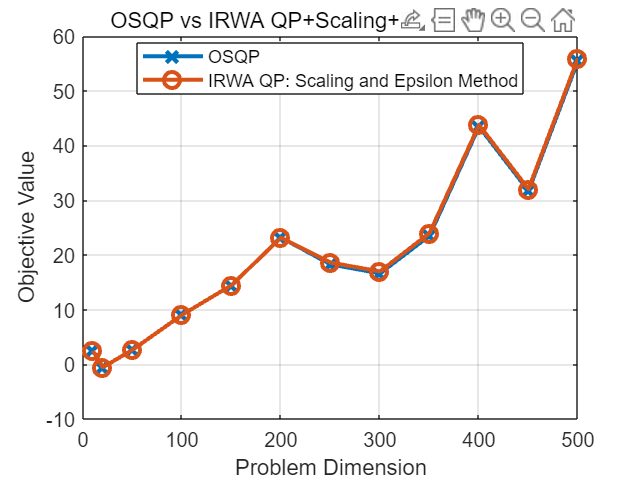


% % Plot results
% figure;
% plot([20, dims], [result_20_scaling, results_scaling], '-o', 'DisplayName', 'QP: Scaling and Epsilon threshold');
% hold on;
% plot([20, dims], [result_20_QP, results_QP], '-s', 'DisplayName', 'QP: Epsilon threshold');
% plot([20, dims], [result_20_QP_origin, results_QP_origin], '-d', 'DisplayName', 'QP Origin');
% plot([20, dims], [result_20_QP_scaling_no_max, results_scaling_no_max], '-^', 'DisplayName', 'QP: Scaling');
% plot([20, dims], [result_20_osqp, results_osqp], '-x', 'DisplayName', 'OSQP');
% hold off;
% 
% xlabel('Problem Dimension');
% ylabel('Objective Value');
% title('Comparison of IRWA QP Methods');
% legend('Location', 'best');
% grid on;


% Plot results
figure;
plot(dims, results_osqp, '-x', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'OSQP');
hold on;
plot(dims, results_scaling, '-o', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'IRWA QP: Scaling and Epsilon Method');
hold off;

xlabel('Problem Dimension');
ylabel('Objective Value');
title('OSQP vs IRWA QP+Scaling+Epsilon Method');
legend('Location', 'NorthWest');
grid on;

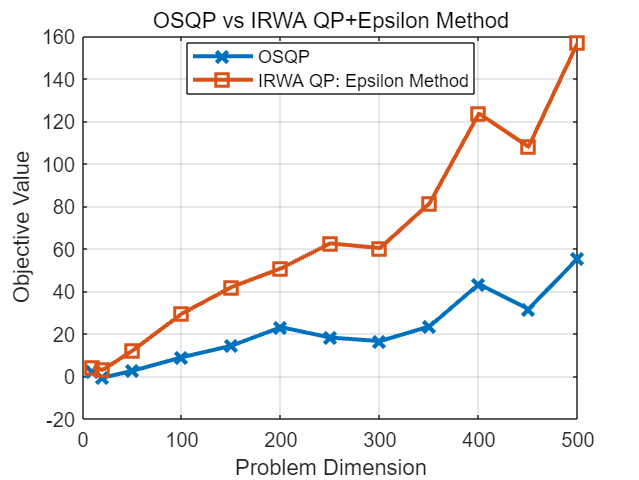


figure;
plot(dims, results_osqp, '-x', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'OSQP');
hold on;
plot(dims, results_QP, '-s', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'IRWA QP: Epsilon Method');
hold off;

xlabel('Problem Dimension');
ylabel('Objective Value');
title('OSQP vs IRWA QP+Epsilon Method');
legend('Location', 'NorthWest');
grid on;

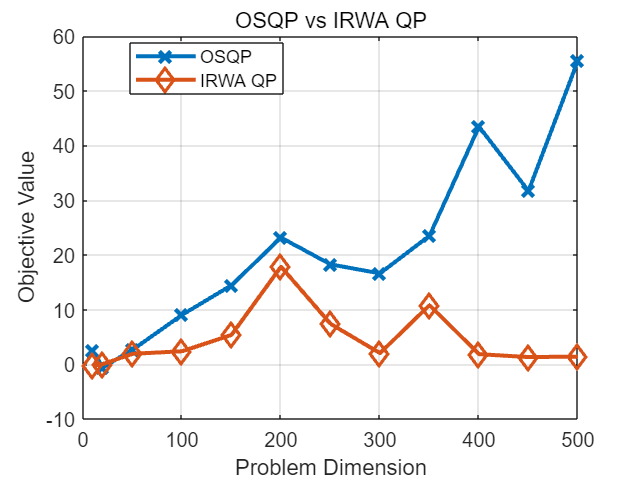


figure;
plot(dims, results_osqp, '-x', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'OSQP');
hold on;
plot(dims, results_QP_origin, '-d', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'IRWA QP');
hold off;

xlabel('Problem Dimension');
ylabel('Objective Value');
title('OSQP vs IRWA QP');
legend('Location', 'NorthWest');
grid on;

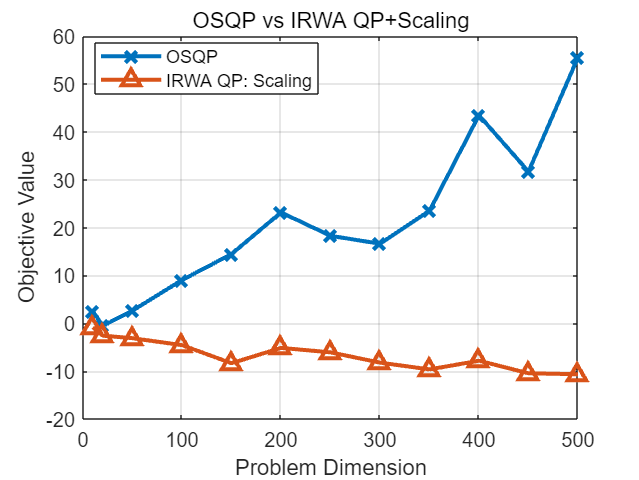


figure;
plot(dims, results_osqp, '-x', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'OSQP');
hold on;
plot(dims, results_scaling_no_max, '-^', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'IRWA QP: Scaling');
hold off;

xlabel('Problem Dimension');
ylabel('Objective Value');
title('OSQP vs IRWA QP+Scaling');
legend('Location', 'NorthWest');
grid on;

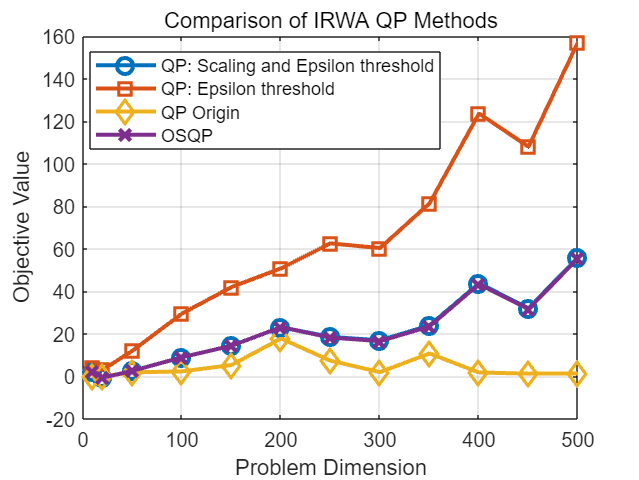

figure;
plot(dims, results_scaling, '-o', 'LineWidth', 2, 'MarkerSize', 8,'DisplayName', 'QP: Scaling and Epsilon threshold');
hold on;
plot(dims, results_QP, '-s', 'LineWidth', 2, 'MarkerSize', 8,'DisplayName', 'QP: Epsilon threshold');
plot(dims, results_QP_origin, '-d', 'LineWidth', 2, 'MarkerSize', 8,'DisplayName', 'QP Origin');
% plot(dims, results_scaling_no_max, '-^', 'LineWidth', 2, 'MarkerSize', 8,'DisplayName', 'QP: Scaling');
plot(dims, results_osqp, '-x', 'LineWidth', 2, 'MarkerSize', 8,'DisplayName', 'OSQP');
hold off;

xlabel('Problem Dimension');
ylabel('Objective Value');
title('Comparison of IRWA QP Methods');
legend('Location', 'best');
grid on;

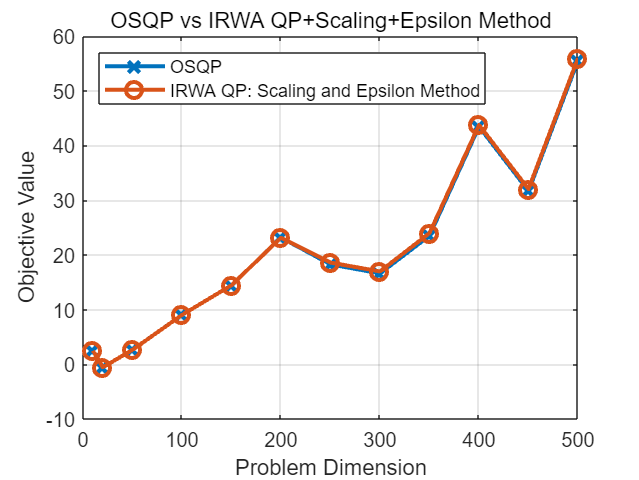

figure;
plot(dims, results_osqp, '-x', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'OSQP');
hold on;
plot(dims, results_scaling, '-o', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'IRWA QP: Scaling and Epsilon Method');
hold off;

xlabel('Problem Dimension');
ylabel('Objective Value');
title('OSQP vs IRWA QP+Scaling+Epsilon Method');
legend('Location', 'NorthWest');
grid on;

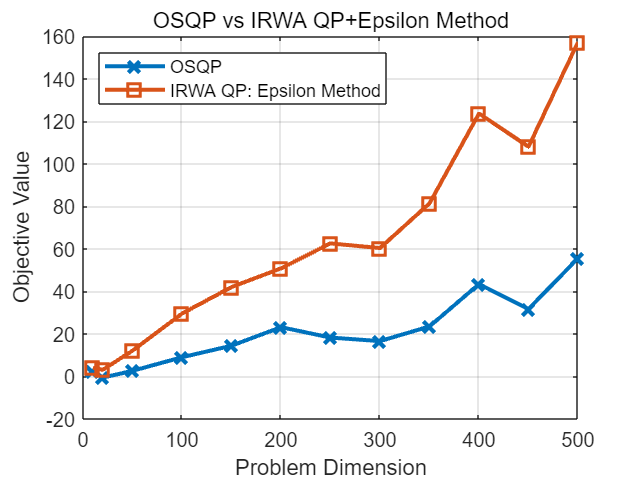


figure;
plot(dims, results_osqp, '-x', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'OSQP');
hold on;
plot(dims, results_QP, '-s', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'IRWA QP: Epsilon Method');
hold off;

xlabel('Problem Dimension');
ylabel('Objective Value');
title('OSQP vs IRWA QP+Epsilon Method');
legend('Location', 'NorthWest');
grid on;

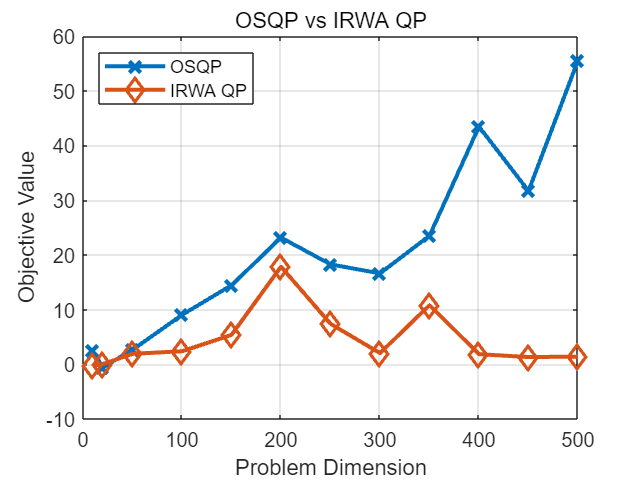


figure;
plot(dims, results_osqp, '-x', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'OSQP');
hold on;
plot(dims, results_QP_origin, '-d', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'IRWA QP');
hold off;

xlabel('Problem Dimension');
ylabel('Objective Value');
title('OSQP vs IRWA QP');
legend('Location', 'NorthWest');
grid on;

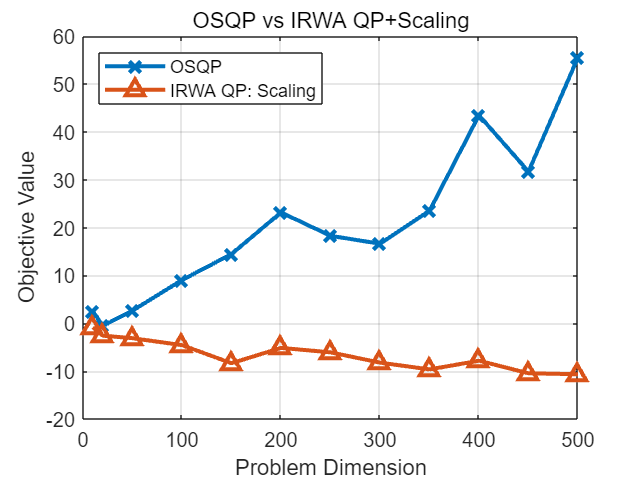


figure;
plot(dims, results_osqp, '-x', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'OSQP');
hold on;
plot(dims, results_scaling_no_max, '-^', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'IRWA QP: Scaling');
hold off;

xlabel('Problem Dimension');
ylabel('Objective Value');
title('OSQP vs IRWA QP+Scaling');
legend('Location', 'NorthWest');
grid on;

function x = IRWA_QP_scaling(A1, A2, b1, b2, g, H)
    A = [A1; A2];
    b = [b1; b2];

    n = size(g, 1);
    m_eq = size(A1, 1);
    m_ineq = size(A2, 1);
    m = size(A, 1);
    epsilon = ones(m, 1);
    x = zeros(n, 1);
    gamma = 0;
    if n<=200
        eta = 0.99;
        M = 10;
    elseif n<1000
        eta = 0.9;
        M = 20;
    else 
        eta = 0.9;
        M = 100;
    end
    prim_tol = 1e-6;
    dual_tol = 1e-6;
    max_iter = 4000;

    scale_eq = 1 / norm(A1, 'fro');
    scale_ineq = 1 / norm(A2, 'fro');  
    scaling_matrix = diag([scale_eq * ones(m_eq, 1); scale_ineq * ones(m_ineq, 1)]);

    A_scaled = scaling_matrix * A;
    b_scaled = scaling_matrix * b;

    for k = 1:max_iter
        Eq = A1 * x;
        Ineq = A2 * x;
        w = [Eq + b1; (max(Ineq, -b2) + b2)];

        w_scaled = scaling_matrix * w;
        % w_scaled =(epsilon.^2 + w_scaled.^2).^(-0.5) + 1 ./ epsilon;
        w_scaled =max((epsilon.^2 + w_scaled.^2).^(-0.5) ,1 ./ epsilon);
        W = diag(w_scaled);

        v = scaling_matrix * [b1; max(-Ineq, b2)];

        H_tilde = H + A_scaled' * W * A_scaled;
        g_tilde = g + A_scaled' * W * v;
        x_next = lsqminnorm(H_tilde, -g_tilde);
        % x_next = conjgrad(H_tilde, -g_tilde,1e-4);

        % Step 2: Update relaxation vector
        q = A_scaled * (x_next - x);
        r = scaling_matrix * ((1 - v) .* (A_scaled * x + b_scaled));

        if all(abs(q) <= M * ((r.^2 + epsilon.^2).^(0.5 + gamma)))
            epsilon = epsilon * eta;
        end
        primal =norm(x_next - x,inf);
        er =norm(epsilon,inf);
        % Step 3: Check stopping criteria
        if primal <= prim_tol && er <= dual_tol
            x = x_next;
            break;
        end
        % x'*H*x/2+g'*x
        x = x_next;
    end
end

function x = IRWA_QP_scaling_no_max(A1, A2, b1, b2, g, H)
    A = [A1; A2];
    b = [b1; bplot2];

    n = size(g, 1);
    m_eq = size(A1, 1);
    m_ineq = size(A2, 1);
    m = size(A, 1);
    epsilon = ones(m, 1);
    x = zeros(n, 1);
    gamma = 0;
    if n<=200
        eta = 0.99;
        M = 10;
    elseif n<1000
        eta = 0.9;
        M = 20;
    else 
        eta = 0.9;
        M = 100;
    end
    prim_tol = 1e-6;
    dual_tol = 1e-6;
    max_iter = 4000;

    scale_eq = 1 / norm(A1, 'fro');
    scale_ineq = 1 / norm(A2, 'fro');  
    scaling_matrix = diag([scale_eq * ones(m_eq, 1); scale_ineq * ones(m_ineq, 1)]);

    A_scaled = scaling_matrix * A;
    b_scaled = scaling_matrix * b;

    for k = 1:max_iter
        Eq = A1 * x;
        Ineq = A2 * x;
        w = [Eq + b1; Ineq + b2];

        w_scaled = scaling_matrix * w;
        % w_scaled =(epsilon.^2 + w_scaled.^2).^(-0.5) + 1 ./ epsilon;
        w_scaled = (epsilon.^2 + w_scaled.^2).^(-0.5);
        W = diag(w_scaled);

        v = scaling_matrix * [b1; max(-Ineq, b2)];

        H_tilde = H + A_scaled' * W * A_scaled;
        g_tilde = g + A_scaled' * W * v;
        x_next = lsqminnorm(H_tilde, -g_tilde);
        % x_next = conjgrad(H_tilde, -g_tilde,1e-4);

        % Step 2: Update relaxation vector
        q = A_scaled * (x_next - x);
        r = scaling_matrix * ((1 - v) .* (A_scaled * x + b_scaled));

        if all(abs(q) <= M * ((r.^2 + epsilon.^2).^(0.5 + gamma)))
            epsilon = epsilon * eta;
        end
        primal =norm(x_next - x,inf);
        er =norm(epsilon,inf);
        % Step 3: Check stopping criteria
        if primal <= prim_tol && er <= dual_tol
            x = x_next;
            break;
        end
        % x'*H*x/2+g'*x
        x = x_next;
    end
end


function x = QP(A1, A2, b1, b2, g, H)
    A = [A1;A2];
    b = [b1;b2];

    n = size(g,1);
    m = size(A,1);
    epsilon = ones(m,1);
    x = zeros(n,1);
    eta = 0.9;
    gamma = 0;
    M = 100;
    prim_tol = 1e-6;
    dual_tol = 1e-11;
    max_iter = 4000;

    for k = 1:max_iter
        Eq = A1*x;
        Ineq = A2*x;
        w = [Eq+b1;(max(Ineq,-b2)+b2)];
        w = (epsilon.^2+w.^2).^(-0.5)+1./epsilon;
        W = diag(w);
        v = [b1;max(-Ineq,b2)];
        H_tilde = H + A' * W * A;
        g_tilde = g + A' * W * v;
        x_next = lsqminnorm(H_tilde,-g_tilde);
        % Step 2: Update relaxation vector
        q = A * (x_next - x);
        r = (1-v).*(A*x+b);
        if all(abs(q) <= M * ((r.^2 + epsilon.^2).^(0.5 + gamma)))
            epsilon = epsilon * eta; %(0,eta*epsilon] exact line search
        end
        
        % Step 3: Check stopping criteria
        if norm(x_next - x) <= prim_tol && norm(epsilon) <= dual_tol
            x = x_next;
            break;
        end
        x = x_next;
    end
end

function x = QP_origin(A1, A2, b1, b2, g, H)
    A = [A1;A2];
    b = [b1;b2];

    n = size(g,1);
    m = size(A,1);
    epsilon = ones(m,1);
    x = zeros(n,1);
    eta = 0.9;
    gamma = 0;
    M = 100;
    prim_tol = 1e-6;
    dual_tol = 1e-11;
    max_iter = 4000;

    for k = 1:max_iter
        Eq = A1*x;
        Ineq = A2*x;
        w = [Eq+b1;Ineq+b2];
        w = (epsilon.^2+w.^2).^(-0.5);
        W = diag(w);
        v = [b1;max(-Ineq,b2)];
        H_tilde = H + A' * W * A;
        g_tilde = g + A' * W * v;
        x_next = lsqminnorm(H_tilde,-g_tilde);
        % Step 2: Update relaxation vector
        q = A * (x_next - x);
        r = (1-v).*(A*x+b);
        if all(abs(q) <= M * ((r.^2 + epsilon.^2).^(0.5 + gamma)))
            epsilon = epsilon * eta; %(0,eta*epsilon] exact line search
        end
        
        % Step 3: Check stopping criteria
        if norm(x_next - x) <= prim_tol && norm(epsilon) <= dual_tol
            x = x_next;
            break;
        end
        x = x_next;
    end
end
